**Exercise 1**

Consider the data sets `lecture6_2_dat.txt` and `lecture6_3_dat.txt` which contain two independent samples from two populations with mean $\mu_1$ and $\mu_2$. let $\delta  = \mu_1 - \mu_2$. Perform a hypothesis test of $H_0 : \delta = 0$ against $H_1 : \delta \neq 0$ for $\alpha = 0.05$ under the assumptions that

(a) the population standard deviations $\sigma_1 = \sigma_2 = 1$ are known, and the sample size is large

(b) the population standard deviations are not known, and the sample size is large.

Specify the rejection region and the value your decision is based on.

x1 = load("data/lecture6_2_dat.txt");
x2 = load("data/lecture6_3_dat.txt");

n1 = length(x1);
n2 = length(x2);
xbar1 = mean(x1);
xbar2 = mean(x2);
s1 = std(x1);
s2 = std(x2);

delta = xbar1 - xbar2;
delta0 = 0;
alpha = 0.05;

zcrit = norminv(1 - alpha/2);

%a
sigma1 = 1;
sigma2 = 1;

Z_a = (delta - delta0) / sqrt(sigma1^2/n1 + sigma2^2/n2);

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 1.1439, xbar2 = 0.7433

fprintf("delta_hat = %.4f", delta);

delta_hat = 0.4006

fprintf("Test statistic Z = %.4f", Z_a);

Test statistic Z = 1.7915

fprintf("Rejection region: |Z| > %.4f", zcrit);

Rejection region: |Z| > 1.9600


if abs(Z_a) > zcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Do not reject H0


%b
Z_b = (delta - delta0) / sqrt(s1^2/n1 + s2^2/n2);

fprintf("s1 = %.4f, s2 = %.4f", s1, s2);

s1 = 1.0755, s2 = 1.0224

fprintf("delta_hat = %.4f", delta);

delta_hat = 0.4006

fprintf("Test statistic Z = %.4f", Z_b);

Test statistic Z = 1.7074

fprintf("Rejection region: |Z| > %.4f", zcrit);

Rejection region: |Z| > 1.9600


if abs(Z_b) > zcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Do not reject H0

**Exercise 2**

Redo Exercise 1 for $H_0 : \delta = 0$ against $H_1 : \delta > 0$.

x1 = load("data/lecture6_2_dat.txt");
x2 = load("data/lecture6_3_dat.txt");

n1 = length(x1);
n2 = length(x2);
xbar1 = mean(x1);
xbar2 = mean(x2);
s1 = std(x1);
s2 = std(x2);

delta = xbar1 - xbar2;
delta0 = 0;
alpha = 0.05;

zcrit = norminv(1 - alpha);

%a
sigma1 = 1;
sigma2 = 1;

Z_a = (delta - delta0) / sqrt(sigma1^2/n1 + sigma2^2/n2);

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 1.1439, xbar2 = 0.7433

fprintf("delta_hat = %.4f", delta);

delta_hat = 0.4006

fprintf("Test statistic Z = %.4f", Z_a);

Test statistic Z = 1.7915

fprintf("Rejection region: |Z| > %.4f", zcrit);

Rejection region: |Z| > 1.6449


if Z_a > zcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Reject H0


%b
Z_b = (delta - delta0) / sqrt(s1^2/n1 + s2^2/n2);

fprintf("s1 = %.4f, s2 = %.4f", s1, s2);

s1 = 1.0755, s2 = 1.0224

fprintf("delta_hat = %.4f", delta);

delta_hat = 0.4006

fprintf("Test statistic Z = %.4f", Z_b);

Test statistic Z = 1.7074

fprintf("Rejection region: |Z| > %.4f", zcrit);

Rejection region: |Z| > 1.6449


if Z_b > zcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Reject H0

**Exercise 3**

Recycled construction material can be used in the base of roadways. In this situation it is important to have control over the resiliency modulus of the material used. Suppose you have material from two locations with measured resiliency modulus as listed in `lecture7.1.location1.txt` and `lecture7.1.location2.txt`. Use a 0.95 level of significance and a hypothesis test to establish (or not) a difference in the mean resiliency modulus under the assumption that the population variances (each location is a population) are equal. You may assume that the populations are normal.

x1 = load("data/lecture7.1.location1.txt");
x2 = load("data/lecture7.1.location2.txt");
alpha = 0.05;

n1 = length(x1);
n2 = length(x2);

xbar1 = mean(x1);
xbar2 = mean(x2);

s1 = std(x1);
s2 = std(x2);

%pooled variance
sp2 = ((n1 - 1)*s1^2 + (n2 - 1)*s2^2) / (n1 + n2 - 2);
sp = sqrt(sp2);

%test statistic
T = (xbar1 - xbar2) / (sp * sqrt(1/n1 + 1/n2));

%degrees of freedom
df = n1 + n2 - 2;

%critical value
tcrit = tinv(1 - alpha/2, df);

fprintf("n1 = %d, n2 = %d", n1, n2);

n1 = 6, n2 = 6

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 656.3333, xbar2 = 579.6667

fprintf("s1 = %.4f, s2 = %.4f", s1, s2);

s1 = 35.7473, s2 = 61.1544

fprintf("Pooled variance sp^2 = %.4f", sp2);

Pooled variance sp^2 = 2508.8667

fprintf("Test statistic T = %.4f", T);

Test statistic T = 2.6511

fprintf("Degrees of freedom = %d", df);

Degrees of freedom = 10

fprintf("Rejection region: |T| > %.4f", tcrit);

Rejection region: |T| > 2.2281


if abs(T) > tcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Reject H0

**Exercise 4**

Redo Exercise 3 not using the assumption that the population variances are equal.

x1 = load("data/lecture7.1.location1.txt");
x2 = load("data/lecture7.1.location2.txt");
alpha = 0.05;

n1 = length(x1);
n2 = length(x2);

xbar1 = mean(x1);
xbar2 = mean(x2);

s1 = std(x1);
s2 = std(x2);

% test statistic
T = (xbar1 - xbar2) / sqrt(s1^2/n1 + s2^2/n2);

% degrees of freedom
df = (s1^2/n1 + s2^2/n2)^2 / ( ((s1^2/n1)^2)/(n1 - 1) + ((s2^2/n2)^2)/(n2 - 1) );

% critical value
tcrit = tinv(1 - alpha/2, df);

fprintf("n1 = %d, n2 = %d", n1, n2);

n1 = 6, n2 = 6

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 656.3333, xbar2 = 579.6667

fprintf("s1 = %.4f, s2 = %.4f", s1, s2);

s1 = 35.7473, s2 = 61.1544

fprintf("Test statistic T = %.4f", T);

Test statistic T = 2.6511

fprintf("Degrees of freedom = %.4f", df);

Degrees of freedom = 8.0597

fprintf("Rejection region: |T| > %.4f", tcrit);

Rejection region: |T| > 2.3030


if abs(T) > tcrit
    fprintf("Decision: Reject H0");
else
    fprintf("Decision: Do not reject H0");
end

Decision: Reject H0

**Exercise 5**

Catalysts are of great importance for the production of gasoline from biomass. The performance of a catalyst can be measured in terms of the amount of produced gasoline. Suppose you have at your disposal two catalysts that in 9 runs produced the amount of gasoline as listed in `lecture7.3.calalyst1.txt` and `lecture7.3.catalyst2.txt`. Check if an assumption about equal variances is reasonable (by comparing the sample variances) and use a hypothesis test with $\alpha = 0.05$ to establish (or not) a difference in the mean values of the two populations (each catalyst is a population). You may assume that the populations are normal.

x1 = load("data/lecture7.3.catalyst1.txt");
x2 = load("data/lecture7.3.catalyst2.txt");
alpha = 0.05;

n1 = length(x1);
n2 = length(x2);

xbar1 = mean(x1);
xbar2 = mean(x2);

s1 = std(x1);
s2 = std(x2);

v1 = s1^2;
v2 = s2^2;

fprintf("n1 = %d, n2 = %d", n1, n2);

n1 = 9, n2 = 9

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 1.3344, xbar2 = 3.7656

fprintf("s1^2 = %.4f, s2^2 = %.4f", v1, v2);

s1^2 = 0.4548, s2^2 = 0.1089


%compare sample variances
var_ratio = max(v1, v2) / min(v1, v2);
fprintf("Variance ratio = %.4f", var_ratio);

Variance ratio = 4.1765


if var_ratio < 2
    fprintf("The sample variances are fairly close, so equal variances seem reasonable");

    % pooled t-test
    sp2 = ((n1 - 1)*v1 + (n2 - 1)*v2) / (n1 + n2 - 2);
    sp = sqrt(sp2);

    T = ((xbar1 - xbar2) - 0) / (sp * sqrt(1/n1 + 1/n2));
    df = n1 + n2 - 2;
    tcrit = tinv(1 - alpha/2, df);
    p = 2 * (1 - tcdf(abs(T), df));

    fprintf("Using pooled two-sample t-test");
    fprintf("Test statistic T = %.4f", T);
    fprintf("Degrees of freedom = %d", df);
    fprintf("Rejection region: |T| > %.4f", tcrit);
    fprintf("p-value = %.6f", p);

    if abs(T) > tcrit
        fprintf("Decision: Reject H0");
    else
        fprintf("Decision: Do not reject H0");
    end

else
    fprintf("The sample variances are not very close, so equal variance does not seem reasonable");

    % t-test
    T = ((xbar1 - xbar2) - 0) / sqrt(v1/n1 + v2/n2);

    df = (v1/n1 + v2/n2)^2 / ( ((v1/n1)^2)/(n1 - 1) + ((v2/n2)^2)/(n2 - 1) );

    tcrit = tinv(1 - alpha/2, df);
    p = 2 * (1 - tcdf(abs(T), df));

    fprintf("Using Welch two-sample t-test");
    fprintf("Test statistic T = %.4f", T);
    fprintf("Degrees of freedom = %.4f", df);
    fprintf("Rejection region: |T| > %.4f", tcrit);
    fprintf("p-value = %.6f", p);

    if abs(T) > tcrit
        fprintf("Decision: Reject H0");
    else
        fprintf("Decision: Do not reject H0");
    end
end

The sample variances are not very close, so equal variance does not seem reasonable

Using Welch two-sample t-test

Test statistic T = -9.7138

Degrees of freedom = 11.6233

Rejection region: |T| > 2.1867

p-value = 0.000001

Decision: Reject H0

**Exercise 6**

Consider again the situation described in Exercise 5. Obtain a 95% confidence interval for the difference in the mean values.

x1 = load("data/lecture7.3.catalyst1.txt");
x2 = load("data/lecture7.3.catalyst2.txt");
alpha = 0.05;

n1 = length(x1);
n2 = length(x2);

xbar1 = mean(x1);
xbar2 = mean(x2);

s1 = std(x1);
s2 = std(x2);

v1 = s1^2;
v2 = s2^2;

delta_hat = xbar1 - xbar2;

fprintf("xbar1 = %.4f, xbar2 = %.4f", xbar1, xbar2);

xbar1 = 1.3344, xbar2 = 3.7656

fprintf("Estimated difference xbar1 - xbar2 = %.4f", delta_hat);

Estimated difference xbar1 - xbar2 = -2.4311

fprintf("s1^2 = %.4f, s2^2 = %.4f", v1, v2);

s1^2 = 0.4548, s2^2 = 0.1089


var_ratio = max(v1,v2) / min(v1,v2);
fprintf("Variance ratio = %.4f", var_ratio);

Variance ratio = 4.1765


if var_ratio < 2
    fprintf("Equal variances seem reasonable.");

    % pooled interval
    sp2 = ((n1 - 1)*v1 + (n2 - 1)*v2) / (n1 + n2 - 2);
    sp = sqrt(sp2);
    df = n1 + n2 - 2;

    margin = tinv(1 - alpha/2, df) * sp * sqrt(1/n1 + 1/n2);

else
    fprintf("Equal variances do not seem reasonable.");

    % Welch interval
    df = (v1/n1 + v2/n2)^2 / ...
        ( ((v1/n1)^2)/(n1 - 1) + ((v2/n2)^2)/(n2 - 1) );

    margin = tinv(1 - alpha/2, df) * sqrt(v1/n1 + v2/n2);
end

Equal variances do not seem reasonable.


CI_low = delta_hat - margin;
CI_high = delta_hat + margin;

fprintf("95%% confidence interval for mu1 - mu2: [%.4f, %.4f]", CI_low, CI_high);

95% confidence interval for mu1 - mu2: [-2.9784, -1.8838]

**Exercise 7**

A producer of cheese wants to have control over the variation of weight of cheese, a sample of which is listed in `lecture7.5.txt`. Plot a histogram of the data and check if the assumption of a normal population seems reasonable. Obtain a 95% confidence interval for the variance of the weight of cheese.

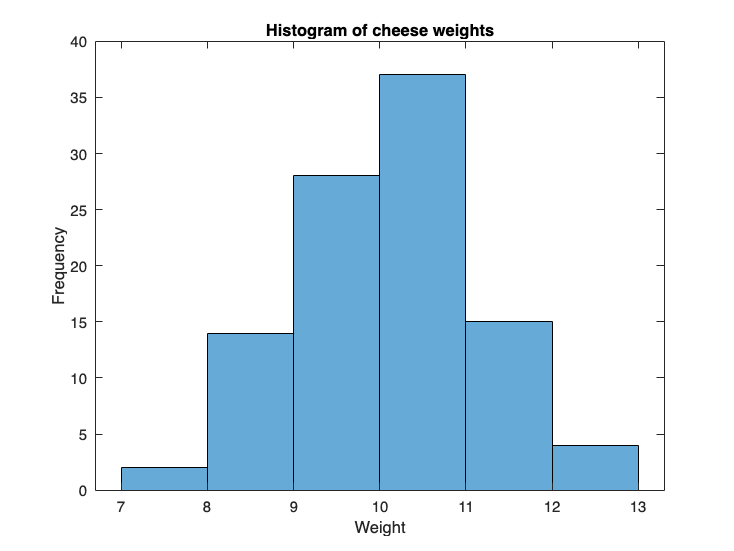

x = load("data/lecture7.5.txt");
alpha = 0.05;

n = length(x);
xbar = mean(x);
s = std(x);
s2 = s^2;

% Histogram
figure;
histogram(x);
xlabel("Weight");
ylabel("Frequency");
title("Histogram of cheese weights");

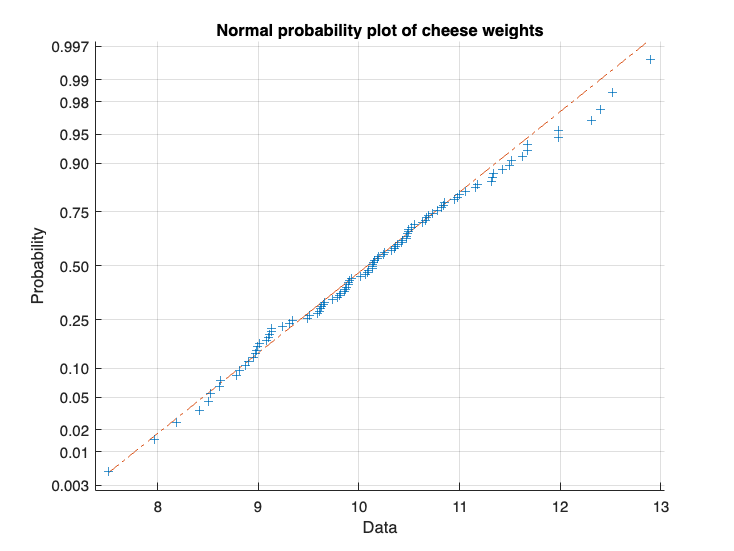


%normal probability plot
figure;
normplot(x);
title("Normal probability plot of cheese weights");


%95% confidence interval for the population variance
chi2_lower = chi2inv(alpha/2, n-1);
chi2_upper = chi2inv(1 - alpha/2, n-1);

var_lower = (n-1)*s2 / chi2_upper;
var_upper = (n-1)*s2 / chi2_lower;

fprintf("n = %d", n);

n = 100

fprintf("Sample mean = %.4f", xbar);

Sample mean = 10.1332

fprintf("Sample variance = %.4f", s2);

Sample variance = 1.0987

fprintf("95%% CI for the variance: [%.4f, %.4f]", var_lower, var_upper);

95% CI for the variance: [0.8470, 1.4827]

**Exercise 8**

In continuation of Exercise 7 suppose that for technical reasons the weight of cheese must be within specified limits $\mu \pm 1$ where $\mu$ is the population mean. Assume that the weight of cheese follows a normal distribution and use the observed sample mean as an estimate for the population mean. Calculate the average percentage of cheese that is not within the specified limits by using the lower limit of the confidence interval obtained in Exercise 7 as the estimate of the population variance. This corresponds to a best case scenario. Do the same by using the upper limit of the confidence interval which corresponds to a worst case scenario.

x = load("data/lecture7.5.txt");
alpha = 0.05;

n = length(x);
xbar = mean(x);
s = std(x);
s2 = s^2;

chi2_lower = chi2inv(alpha/2, n-1);
chi2_upper = chi2inv(1 - alpha/2, n-1);

var_lower = (n-1)*s2 / chi2_upper;
var_upper = (n-1)*s2 / chi2_lower;

%standard deviations corresponding to CI bounds
sigma_best = sqrt(var_lower);   % best case: smallest variance
sigma_worst = sqrt(var_upper);  % worst case: largest variance

%percentage outside the limits
p_best = 2 * (1 - normcdf(1 / sigma_best));
p_worst = 2 * (1 - normcdf(1 / sigma_worst));

fprintf("Sample mean estimate mu_hat = %.4f", xbar);

Sample mean estimate mu_hat = 10.1332

fprintf("95%% CI for variance: [%.4f, %.4f]", var_lower, var_upper);

95% CI for variance: [0.8470, 1.4827]

fprintf("Best case percentage outside limits: %.4f%%", 100*p_best);

Best case percentage outside limits: 27.7217%

fprintf("Worst case percentage outside limits: %.4f%%", 100*p_worst);

Worst case percentage outside limits: 41.1499%